# Lab 1

In order to load the clown image you need to insure it is within the current working directory in the form `clown.mat`.

load clown
clown  (20,319)

ans = 0.1554

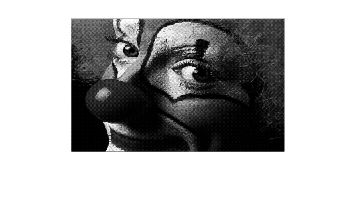

imshow(clown);

## Task 1

#### Attempt 1

function [Out] = rotate_test(In, Theta)

[row, col] = size(In);

centre = [(row+1)/2; (col+1)/2];

% rotation matrix
R = [cos(Theta) sin(Theta); -sin(Theta) cos(Theta)];

R_inv = inv(R); 

Out = [];

for i = 1:row

    new_row = [];

    for j = 1:col

        source_pixel = R_inv * ([i;j]-centre) + centre;

        y = source_pixel(1);
        x = source_pixel(2);

        updated_value = In(round(y),round(x));

        new_row = horzcat(new_row, updated_value);
    end

    Out = vertcat(Out, new_row);
    end
end

Testing with a smal sample image (so we can clearly see what is happening):

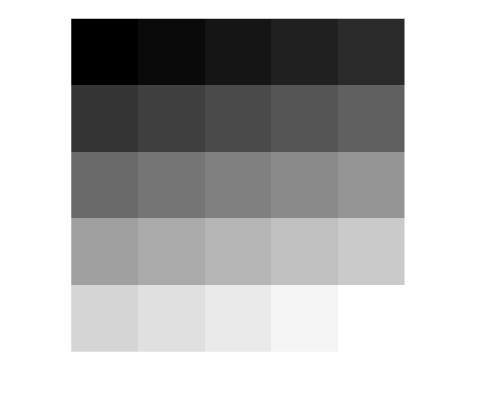

image_1 = [1 2 3 4 5; 6 7 8 9 10; 11 12 13 14 15; 16 17 18 19 20; 21 22 23 24 25];
angle=1.57079633;
image_2 = rotate_test(image_1, angle);
imshow(image_1, [], InitialMagnification=10000);

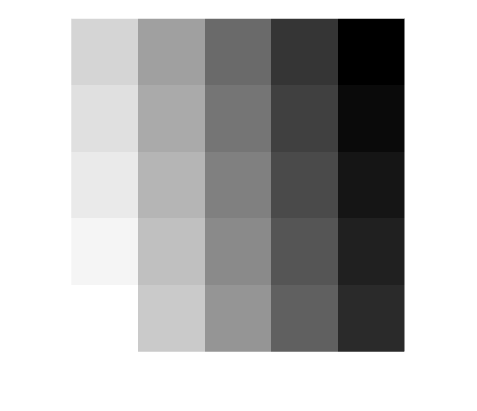

imshow(image_2, [], InitialMagnification=10000);

This works for a basic rotation of angle=1.57079633; (90 degrees) but fails for other angles e.g. 30 degrees - why?

% image_1 = [1 2 3 4 5; 6 7 8 9 10; 11 12 13 14 15; 16 17 18 19 20; 21 22 23 24 25];
% angle = 0.52359878; %30 degrees in radians
% image_2 = rotate_test(image_1, angle);
% imshow(image_1, [], InitialMagnification=10000);
% imshow(image_2, [], InitialMagnification=10000);

You get the error: `Index in position 2 is invalid. Array indices must be positive integers or logical values. `

When rotating by 90 degrees each pixel maps onto another pixel location - but when rotating by 30 degrees the transformed coordinates can fall outside of the bounds of the original image. Pixels may also be float values - which means it is not possible to assign them to a new position. To fix this bounds checking needs to be used.

#### Attempt 2

function [Out] = rotate(In, Theta)

[row, col] = size(In);

centre = [(row+1)/2; (col+1)/2]; %may want to add rounding for safety 

% rotation matrix
R = [cos(Theta) sin(Theta); -sin(Theta) cos(Theta)];

R_inv = inv(R);

Out = zeros(row, col); % this was changed from last time
% by pre-assigning the output with zeroes this can improve processing
% speeds

for i = 1:row

    for j = 1:col
        
        source_pixel = R_inv * ([i;j]-centre) + centre;
        % a different approach can be used for R_inv to improve speed
        
        y = source_pixel(1);
        x = source_pixel(2);
        
        % this was the key bit I was missing before
        if round(y) >= 1 && round(y) <= row && round(x) >= 1 && round(x) <= col
       
            Out(i,j) = In(round(y), round(x));
        end
        % by default the pixels will be black
        % if x and y fall inside the bounds of the image then the output
        % will be painted
    end
end

end

Testing again:

image_1 = [1 2 3 4 5; 6 7 8 9 10; 11 12 13 14 15; 16 17 18 19 20; 21 22 23 24 25];
angle = 0.52359878; %30 degrees in radians
image_2 = rotate(image_1, angle);
imshow(image_1, [], InitialMagnification=10000);

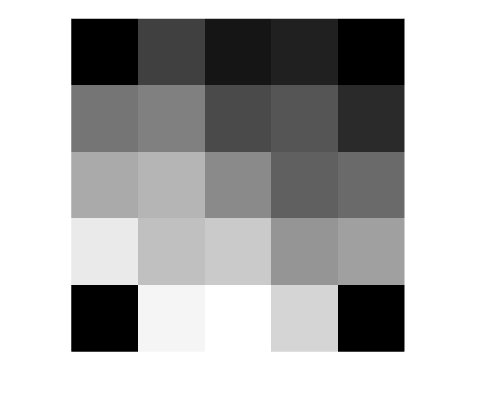

imshow(image_2, [], InitialMagnification=10000);

Testing with clown:

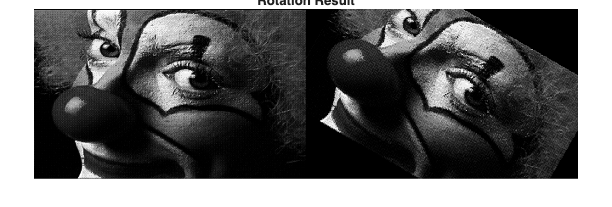

load clown
angle = 0.52359878; %30 degrees in radians
image_2 = rotate(clown, angle);

figure;
montage({clown, image_2});
title("Rotation Result")

This time it works 

## Task 2

From the provided equation we need to work out what the reverse mapping would be. Need to rearrange the equation in terms of the source pixel rather than the destination pixel. 

The working for this is in `Shear Reverse Mapping.md `or `shear-reverse-mapping.png `using latex

Then we should be able to follow a similar approach:

function [Out] = shear(In, Xshear, Yshear)

[row, col] = size(In);

centre = [(row+1)/2; (col+1)/2]; %may want to add rounding for safety 

% shear matrix
S = [1 Xshear; Yshear 1];

S_inv = inv(S);

Out = zeros(row, col); % this was changed from last time
% by pre-assigning the output with zeroes this can improve processing
% speeds

for i = 1:row

    for j = 1:col
        
        source_pixel = S_inv * ([i;j]-centre) + centre;
        % a different approach can be used for R_inv to improve speed
        
        y = source_pixel(1);
        x = source_pixel(2);
        
        % this was the key bit I was missing before
        if round(y) >= 1 && round(y) <= row && round(x) >= 1 && round(x) <= col
       
            Out(i,j) = In(round(y), round(x));
        end
        % by default the pixels will be black
        % if x and y fall inside the bounds of the image then the output
        % will be painted
    end
end

end

Testing with clown:

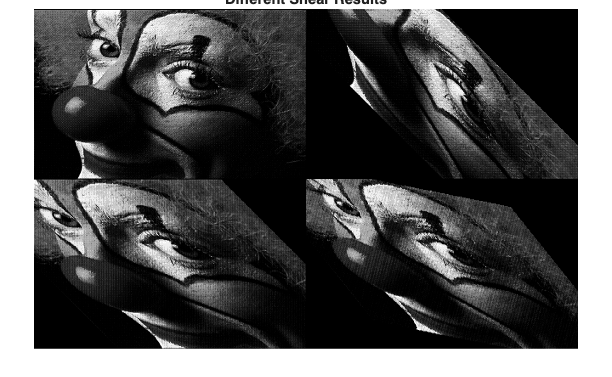

image_1 = [1 2 3 4 5; 6 7 8 9 10; 11 12 13 14 15; 16 17 18 19 20; 21 22 23 24 25];

Xshear=1; 
Yshear=0;

image_2 = shear(clown, Xshear, Yshear);

Xshear=0; 
Yshear=1;
image_3 = shear(clown, Xshear, Yshear);

Xshear=0.2; 
Yshear=0.8;
image_4 = shear(clown, Xshear, Yshear);

figure;
montage({clown, image_2, image_3, image_4});
title("Different Shear Results")